# Avances Filtro Adaptativo

Gallegos Ruiz Diana Abigail

13/06/2022

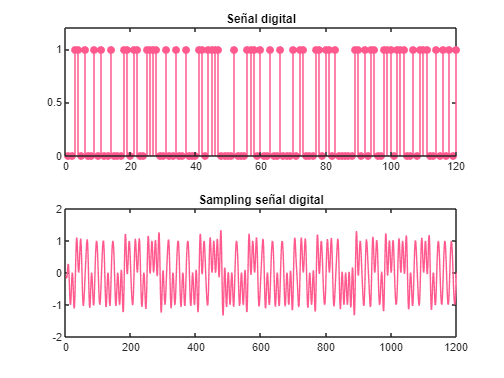

clc
close all
clear all
%------------ FUNCIÓN SAMPLING  --------------
n=1:50;
ft=sinc(2*pi*(n-15)/31.4);


% -------------- SECUENCIA DE BITS - ----------
num = randperm(255,15);
numb=cellstr(dec2bin(num));
for i=1:length(numb) %Concatenar secuencia de bits
    if i==1 || i==2
        vec=strcat(numb(1),numb(2));
    else
        vec= strcat(vec,numb(i));
    end    
end

vec=char(vec);

%-------------   GRÁFICA SECUENCIA DE BITS    ------------
vec=char(vec);
for i=1:length(vec)
    dig(i)=str2double(vec(i));
end


figure(1)
tiledlayout(2,1)
nexttile
stem(dig,'filled','Color','#ff598e')
title('Señal digital')
ylim([0.00 1.20])


%-------GRÁFICA DE LA SECUENCIA GENERADA  -------------------


k=length(vec)*10;
fdn=zeros(1,k);
n=1:k;
for i=1:length(vec)
    if vec(i) == '0' % Mandará un 0
      fdn= fdn-sinc(2*pi*(n-5-(i*10))/31.4);
    else % Mandará un 1
      fdn= fdn+sinc(2*pi*(n-5-(i*10))/31.4); 
    end
end
nexttile
plot(fdn,'Color','#ff598e')
title('Sampling señal digital')

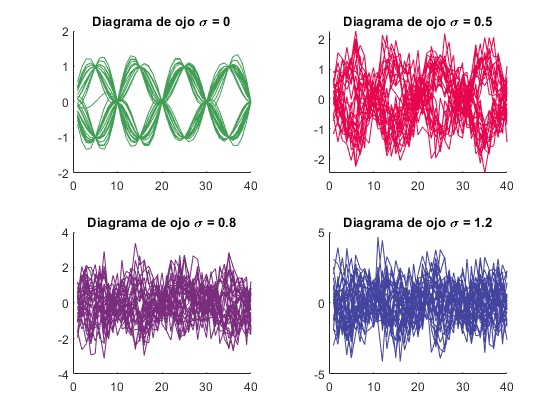



%Ruido agregado a la señal
ruido1= fdn+ randn(1,k)*0.5;
ruido2= fdn+ randn(1,k)*0.8;
ruido3 = fdn+ randn(1,k)*1.2;

%----------------- DIAGRAMA DE OJO SIGMA = 0 ------------------------------

k=length(fdn);
ojo=zeros(1,40);
figure(2)
tiledlayout('flow')
nexttile

for j=1:40:k
    for i=1:40
        ojo(i)=fdn(j+i-1);   
    end
    hold on
    plot(ojo,'Color','#429e55')
end

title('Diagrama de ojo \sigma = 0')

%----------------- DIAGRAMA DE OJO SIGMA = 0.5 ----------------------------
k=length(fdn);
nexttile
for j=1:40:k
    for i=1:40
        ojo(i)=ruido1(j+i-1);   
    end
    hold on
    plot(ojo,'Color','#e8054d')
end
title('Diagrama de ojo \sigma = 0.5')


%----------------- DIAGRAMA DE OJO SIGMA = 0.8 ----------------------------

nexttile
for j=1:40:k
    for i=1:40
        ojo(i)=ruido2(j+i-1);   
    end
    hold on
    plot(ojo,'Color','#7a2d7d')
end
title('Diagrama de ojo \sigma = 0.8')

%----------------- DIAGRAMA DE OJO SIGMA = 1.2 ----------------------------

nexttile
for j=1:40:k
    for i=1:40
        ojo(i)=ruido3(j+i-1);   
    end
    hold on
    plot(ojo,'Color','#42449e')
end
title('Diagrama de ojo \sigma = 1.2')

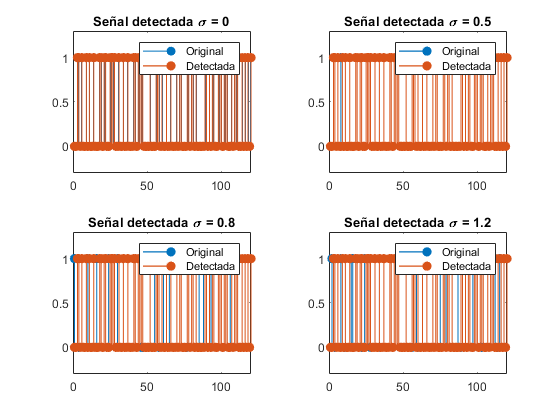



%--------------------------  DETECTOR -------------------------------------


k=length(fdn);

y1=convD(fdn,dig,1);
y2=convD(ruido1,dig,1);
y3=convD(ruido2,dig,1);
y4=convD(ruido3,dig,1);

figure (3)
tiledlayout('flow')
nexttile
stem(y1,'MarkerFaceColor','#0072BD', 'MarkerEdgeColor','#0072BD')
hold on 
stem(dig,'LineWidth',1,'MarkerFaceColor','#D95319','MarkerEdgeColor','#D95319')
legend('Original','Detectada')
title('Señal detectada \sigma = 0')
ylim([-0.3,1.3])
nexttile
stem(y2,'LineWidth',1,'MarkerFaceColor','#0072BD','MarkerEdgeColor','#0072BD')
hold on 
stem(dig,'LineWidth',1,'MarkerFaceColor','#D95319','MarkerEdgeColor','#D95319')
legend('Original','Detectada ')
title('Señal detectada \sigma = 0.5')
ylim([-0.3,1.3])
nexttile
stem(y3,'LineWidth',1,'MarkerFaceColor','#0072BD','MarkerEdgeColor','#0072BD')
hold on 
stem(dig,'LineWidth',1,'MarkerFaceColor','#D95319', 'MarkerEdgeColor','#D95319')
legend('Original','Detectada')
title('Señal detectada \sigma = 0.8')
ylim([-0.3,1.3])
nexttile
stem(y4,'LineWidth',1,'MarkerFaceColor','#0072BD','MarkerEdgeColor','#0072BD')
hold on 
stem(dig,'LineWidth',1,'MarkerFaceColor','#D95319','MarkerEdgeColor','#D95319')
legend('Original','Detectada')
title('Señal detectada \sigma = 1.2')
ylim([-0.3,1.3])

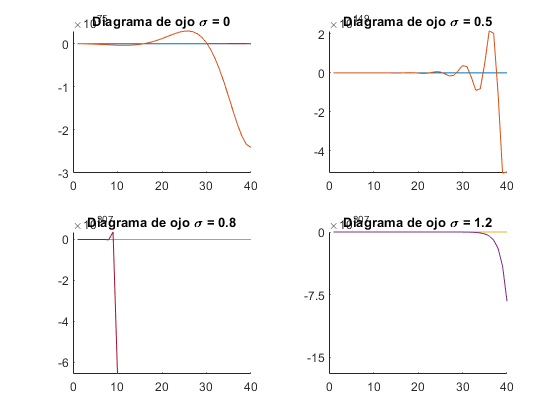



%------------- SEÑAL g(n) -------------------



 gn = filtradaAdap(fdn,fdn,0.2); 
 gn1 = filtradaAdap(fdn, ruido1, 0.2);
 gn2 = filtradaAdap(fdn, ruido2, 0.2); 
 gn3 = filtradaAdap(fdn, ruido3, 0.2); 
   
%----------------- DIAGRAMA DE OJO SIGMA = 0 ------------------------------

k=length(fdn);
ojo=zeros(1,40);
figure(4)
tiledlayout('flow')
nexttile

for j=1:40:k
    for i=1:40
        ojo(i)=gn(j+i-1);   
    end
    hold on
    plot(ojo)
end

title('Diagrama de ojo \sigma = 0')

%----------------- DIAGRAMA DE OJO SIGMA = 0.5 ----------------------------
k=length(fdn);
nexttile
for j=1:40:k
    for i=1:40
        ojo(i)=gn1(j+i-1);   
    end
    hold on
    plot(ojo)
end
title('Diagrama de ojo \sigma = 0.5')


%----------------- DIAGRAMA DE OJO SIGMA = 0.8 ----------------------------

nexttile
for j=1:40:k
    for i=1:40
        ojo(i)=gn2(j+i-1);   
    end
    hold on
    plot(ojo)
end
title('Diagrama de ojo \sigma = 0.8')

%----------------- DIAGRAMA DE OJO SIGMA = 1.2 ----------------------------

nexttile
for j=1:40:k
    for i=1:40
        ojo(i)=gn3(j+i-1);   
    end
    hold on
    plot(ojo)
end
title('Diagrama de ojo \sigma = 1.2')

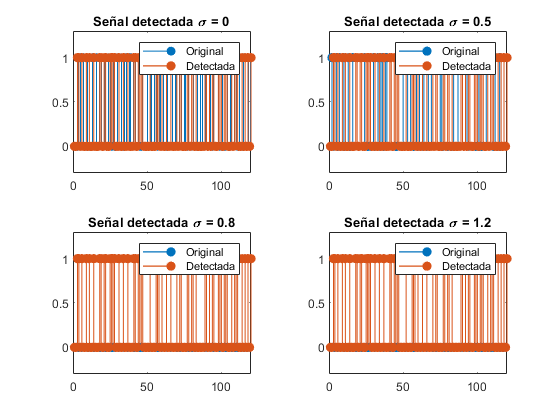


%---------------------- SEÑAL DETECTADA FILTRO ----------------------------

 %Vuelve a pasar por el detector

yf1=convD(gn,dig,1);
yf2=convD(gn1,dig,1);
yf3=convD(gn2,dig,1);
yf4=convD(gn3,dig,1);



figure (5)
tiledlayout('flow')
nexttile
stem(yf1,'MarkerFaceColor','#0072BD', 'MarkerEdgeColor','#0072BD')
hold on 
stem(dig,'LineWidth',1,'MarkerFaceColor','#D95319','MarkerEdgeColor','#D95319')
legend('Original','Detectada')
title('Señal detectada \sigma = 0')
ylim([-0.3,1.3])
nexttile
stem(yf2,'LineWidth',1,'MarkerFaceColor','#0072BD','MarkerEdgeColor','#0072BD')
hold on 
stem(dig,'LineWidth',1,'MarkerFaceColor','#D95319','MarkerEdgeColor','#D95319')
legend('Original','Detectada')
title('Señal detectada \sigma = 0.5')
ylim([-0.3,1.3])
nexttile
stem(yf3,'LineWidth',1,'MarkerFaceColor','#0072BD','MarkerEdgeColor','#0072BD')
hold on 
stem(dig,'LineWidth',1,'MarkerFaceColor','#D95319', 'MarkerEdgeColor','#D95319')
legend('Original','Detectada')
title('Señal detectada \sigma = 0.8')
ylim([-0.3,1.3])
nexttile
stem(yf4,'LineWidth',1,'MarkerFaceColor','#0072BD','MarkerEdgeColor','#0072BD')
hold on 
stem(dig,'LineWidth',1,'MarkerFaceColor','#D95319','MarkerEdgeColor','#D95319')
legend('Original','Detectada')
title('Señal detectada \sigma = 1.2')
ylim([-0.3,1.3])



%FUNCIÓN PARA DETECTAR 1 & 0 

function y = convD(x,dig,num)
 k=length(x);
detectada= zeros(1,length(dig));
jj=1;
while(jj<length(dig))
    for i=15:10*num:k
         detectada(jj)= x(i-1);
         jj=jj+1;
    end
end

    for i=1:length(detectada)
        if detectada(i) >= 0
            y(i)=1;
        else
            y(i)=0;
        end
    end
end



%FUNCIÓN DE FILTRO ADAPTATIVO

function yn=filtradaAdap(fn,fc,miu)
    dn= fn+fc;
    ha= dsp.LMSFilter('Length',15,'Method','LMS','StepSize',miu);
    [y,e] = ha(fn',dn');
    
    yn=filter(y,e,fc);
end